jsonstring = fileread('2022-08-02-01.json');
dataStruct =  jsondecode(jsonstring);


sig_reversal_starts(1:length(dataStruct.reversal_events)) = nan;
sig_reversal_ends(1:length(dataStruct.reversal_events)) = nan;
frame_rate = 1.67;


for i = 1:length(sig_reversal_starts)
    rev_start = dataStruct.reversal_events(i,1);
    rev_end = dataStruct.reversal_events(i,2);
    timeing = rev_end - rev_start;
    if (rev_end - rev_start) >= round(8*frame_rate)
        sig_reversal_starts(i) = rev_start;
        sig_reversal_ends(i) = rev_end;
    end
end

sig_reversal_starts= rmmissing(sig_reversal_starts);
sig_reversal_ends = rmmissing(sig_reversal_ends);
num_reversals = length(sig_reversal_starts);

num_neurons = dataStruct.num_neurons;

before_traces(1:num_reversals, 1:num_neurons) = nan;
after_traces(1:num_reversals, 1:num_neurons) = nan;
trace_array = dataStruct.trace_array;


for neuron = 1:num_neurons
    for i = 1:num_reversals
        before_traces(i, neuron) = mean(trace_array(neuron,(sig_reversal_starts(i)-round(2*frame_rate)):(sig_reversal_starts(i))));
        after_traces(i, neuron) = mean(trace_array(neuron,(sig_reversal_starts(i)+round(6*frame_rate)):(sig_reversal_starts(i)+round(8*frame_rate))));
    end
end

mean_before = mean(before_traces);
mean_after = mean(after_traces);

mean_diff= mean_after - mean_before;

acceptable_times = (1+round(2*frame_rate)):(1599-round(8*frame_rate));

rand_before_traces(1:num_reversals, 1:num_neurons) = nan;
rand_after_traces(1:num_reversals, 1:num_neurons) = nan;
rand_trace_diffs(1:10000,1:num_neurons) = nan;

for trial = 1:10000
    random_indices = randperm(length(acceptable_times),num_reversals);
    random_times = acceptable_times(random_indices);
    for neuron = 1:num_neurons
        for i = 1:num_reversals
            rand_before_traces(i,neuron) = mean(trace_array(neuron, (random_times(i)-round(2*frame_rate)):(random_times(i))));
            rand_after_traces(i,neuron) = mean(trace_array(neuron, (random_times(i)+round(6*frame_rate)):(random_times(i)+round(8*frame_rate))));
        end
    end
    rand_mean_before = mean(rand_before_traces);
    rand_mean_after = mean(rand_after_traces);
    rand_trace_diffs(trial,1:num_neurons) = rand_mean_after - rand_mean_before;
end


rand_means = mean(rand_trace_diffs);
rand_stds = std(rand_trace_diffs);
suspected_neurons(1:num_neurons) = nan;
suspected_neuron_names = strings(num_neurons, 1);
abs_bound = prctile(abs(rand_trace_diffs), (1-(0.05/length(fieldnames(dataStruct.labeled))))*100);
numbered_neurons = fieldnames(dataStruct.labeled);
labeled_neurons(length(numbered_neurons)) = nan;
neuron_labels(1:length(numbered_neurons)) = nan;


for i = 1:length(numbered_neurons)
    labeled_neurons(i) = str2double(strrep(numbered_neurons{i},'x',''));
end 


for i = 1:num_neurons
    if  ismember(i,labeled_neurons)
        suspected_neurons(1,i)=i;
        suspected_neuron_names(i) = dataStruct.labeled.(numbered_neurons{find(labeled_neurons==i)}).neuron_class;
    end
end

suspected_neurons = rmmissing(suspected_neurons);
suspected_neuron_names = suspected_neuron_names(suspected_neuron_names ~= '');
event_trace(1:length(sig_reversal_starts), 1:17)= nan;
avg_event_trace(1:length(suspected_neurons), 1:17)= nan;
std_event_trace(1:length(suspected_neurons), 1:17)= nan;

final_ordered_neuron_names = strings(length(suspected_neurons), 1);

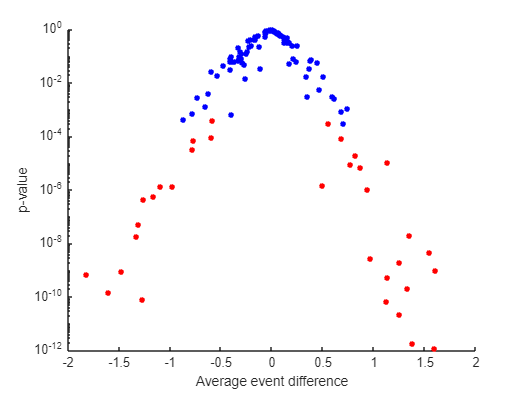


figure;
hold on;
set(gca,'yscale','log');
xlabel('Average event difference')
ylabel('p-value')
neuron_order_numbers = 1;

for i = 1:length(suspected_neurons)

    point_value = mean_diff(suspected_neurons(i));
    mu = rand_means(suspected_neurons(i));
    this_std = rand_stds(suspected_neurons(i));
    cdfValue = normcdf(point_value,mu,this_std);
    p_value = 2 * min(cdfValue, 1 - cdfValue);
    
    if abs(mean_diff(suspected_neurons(i))) >= abs_bound(suspected_neurons(i))
        scatter(point_value,p_value,20,'red','filled');
        final_ordered_neuron_names(neuron_order_numbers) = suspected_neuron_names(i);
        neuron_order_numbers = neuron_order_numbers + 1;

    else
        scatter(point_value,p_value,20,'blue','filled');
    end


    % figure;
    % hold on;
    % 
    % for event = 1:length(sig_reversal_starts)
    %     event_trace(event,:) = trace_array(suspected_neurons(i),round((sig_reversal_starts(event)-2*frame_rate)):round((sig_reversal_starts(event)+8*frame_rate)));
    % end
    % 
    % avg_event_trace(i,:) = mean(event_trace);
    % std_event_trace(i,:)= std(event_trace);
    % plot((-3:13)/frame_rate,avg_event_trace(i,:));
    % xlabel('Time (s)');
    % ylabel('Average Delta(f)/f');
    % xregion(0,8);
    % title(compose('%s Neuron',suspected_neuron_names(i)));
    % patch([(-3:13)/frame_rate flip((-3:13)/frame_rate)], [avg_event_trace(i,:)-std_event_trace(i,:) flip(avg_event_trace(i,:)+std_event_trace(i,:))], 'b', 'FaceAlpha', .5 ,'EdgeColor', 'none');
    % lgd= legend('Average Delta(f)/f','stimulation period','standard deviation');
    % fontsize(lgd,14,'points')
    % hold off;

    % figure;
    % hold on;
    % plot((1:1600)*(1/frame_rate),trace_array(suspected_neurons(i),1:1600));
    % title(compose('%s Neuron',suspected_neuron_names(i)));
    % xlim([0 round(1600*(1/frame_rate))]);
    % xlabel('Time (s)');
    % ylabel('Delta(f)/f');
    % xregion(dataStruct.reversal_events(1:49,1)/frame_rate, dataStruct.reversal_events(1:49,2)/frame_rate);
    % hold off;
end



final_ordered_neuron_names = final_ordered_neuron_names(final_ordered_neuron_names ~= '');
disp(sort(final_ordered_neuron_names))

    "ADE"
    "AIB"
    "AIB"
    "AIM"
    "ASG"
    "ASG"
    "AUA"
    "AUA"
    "AVA"
    "AVA"
    "AVE"
    "AVE"
    "AVL"
    "AWA"
    "BAG"
    "BAG"
    "CEP"
    "IL1"
    "RIB"
    "RID"
    "RIH"
    "RIM"
    "RIP"
    "RMD"
    "RME"
    "RME"
    "RME"
    "URB"
    "URX"
    "URY"
    "URY"
    "URY"
    "URY"

